Каабнов Степан. Домашнее задание по символьным вычислениям.

Номер 1. Разложить полином на множители.

%...
syms x y;
f1 = x^5 + 4*x^4 - 2*x^3 - 14*x^2 - 3*x - 18;
f2 = x^3 + x^2 * y + x^2 - 2*x*y^2 + x*y - 2*y^2;
factor(f1)

$$ans = \left(\begin{array}{cccc} x-2 & x^{2}+1 & x+3 & x+3 \end{array}\right)$$

factor(f2)

$$ans = \left(\begin{array}{ccc} x+1 & x-y & x+2\,y \end{array}\right)$$

Номер 2. Вычислить предел

syms x h;
f1 = x * exp(-x);
limit(f1, x, Inf)

$$ans = 0$$


f2 = tan(x) ^ tan(2*x);
limit(f2, x, pi/4)

$$ans = {\mathrm{e}}^{-1}$$


f3 = atan(1/(1-x));
limit(f3, x, 1, 'right')

$$ans = -\frac{\pi }{2}$$


f4 = (7*x^3 + x^2 - 1)/(5*x^2 + 2*x + 1);
limit(f4, x, Inf)

$$ans = \infty$$


f5 = (sqrt(x + h) - sqrt(x))/h

$$f5 = \frac{\sqrt{h+x}-\sqrt{x}}{h}$$

limit(f5, x, 0)

$$ans = \frac{1}{\sqrt{h}}$$

Номер 3. Найти производную функции, упростить результат.

syms x;

f1 = atan(x)/2 - x/(2*(1+x^2))^2;
simplify(diff(f1))

$$ans = \frac{2\,x^{4}+7\,x^{2}+1}{4\,{\left(x^{2}+1\right)}^{3}}$$


f2 = 3*x^4 - 14*x^3 + 12*x^2 + 24*x + 6;
simplify(diff(f2))

$$ans = 6\,\left(2\,x+1\right)\,{\left(x-2\right)}^{2}$$


f3 = (sin(3*x) - cos(3*x))^2;
simplify(diff(f3))

$$ans = -6\,\cos\left(6\,x\right)$$


f4 = log(x^2 + 2)/2 + (2-x)/(4*(x^2 + 2)) - atan(x/sqrt(2))/(4*sqrt(2))

$$f4 = \frac{\log\left(x^{2}+2\right)}{2}-\frac{x-2}{4\,x^{2}+8}-\frac{\sqrt{2}\,\mathrm{atan}\left(\frac{\sqrt{2}\,x}{2}\right)}{8}$$

simplify(diff(f4))

$$ans = \frac{x^{3}+x-1}{{\left(x^{2}+2\right)}^{2}}$$


f5 = log((x-3)/(x+2))/6

$$f5 = \frac{\log\left(\frac{x-3}{x+2}\right)}{6}$$

simplify(diff(f5))

$$ans = -\frac{5}{6\,\left(-x^{2}+x+6\right)}$$

Номер 4. Вычислить значения интеграла. 

syms x

f1 = sqrt(1 - x^2)/x^2;
int(f1)

$$ans = -\mathrm{asin}\left(x\right)-\frac{\sqrt{1-x^{2}}}{x}$$


f2 = 1/(sin(x)^3);
int(f2)

$$ans = \frac{\log\left(\tan\left(\frac{x}{2}\right)\right)}{2}-\frac{\cos\left(x\right)}{2\,{\sin\left(x\right)}^{2}}$$


f3 = (sin(2*x)+1)^(1/7) * cos(2*x);
int(f3)

$$ans = \frac{7\,{\left(\sin\left(2\,x\right)+1\right)}^{8/7}}{16}$$


f4 = 15*(sqrt(x + 3))/((x+3)^2 * sqrt(x));
int(f4, 1/8, 1)

$$ans = 3$$


f5 = 1/(1+x^2);
int(f5, 0, Inf)

$$ans = \frac{\pi }{2}$$


f6 = 1/(x^2 - 1);
int(f6, -2, 2) % Этот интеграл не существует, т.к функция имеет разрыв второго порядка

$$ans = \mathrm{NaN}$$


f7 = log(sin(x));
int(f7, 0, pi/2)

$$ans = -\frac{\pi \,\log\left(2\right)}{2}$$

Номер 5. Вычислить сумму ряда.

syms x k;

s1 = 1/(k^2);
symsum(s1, k, 1, Inf)

$$ans = \frac{\pi^{2}}{6}$$


s2 = (-1)^((k^2 + k)/k) * k/(2^k);
symsum(s2, k, 1, Inf)

$$ans = \sum_{k=1}^{\infty }\frac{{\left(-1\right)}^{\frac{k^{2}+k}{k}}\,k}{2^{k}}$$


s3 = x^k;
symsum(s3, k, 0, Inf)

$$ans = \left\{ \begin{array}{cl} \infty & \text{ if }1\leq x\\ -\frac{1}{x-1} & \text{ if }\left|x\right|<1 \end{array}\right.$$


s4 = (3 - x)^(2*k) / (sqrt(k));
symsum(s4, k, 0, Inf)

$$ans = \sum_{k=0}^{\infty }\frac{{\left(x-3\right)}^{2\,k}}{\sqrt{k}}$$


s5 = 1/(x-k)^3;
symsum(s5, k, -Inf, Inf)

$$ans = \left\{ \begin{array}{cl} \frac{\psi^{\prime \prime }(-x)}{2}-\frac{1}{x^{3}}-\frac{\psi^{\prime \prime }(x)}{2} & \text{ if }x\notin \mathbb{Z} \end{array}\right.$$

Номер 6.  Разложить функцию в ряд Тейлора до степени 'n' в окрестности указанной точки 'a'

syms x;

f1 = exp(x);
taylor(f1, x, 'ExpansionPoint', 1, 'Order', 6)

$$ans = \mathrm{e}+\mathrm{e}\,\left(x-1\right)+\frac{\mathrm{e}\,{\left(x-1\right)}^{2}}{2}+\frac{\mathrm{e}\,{\left(x-1\right)}^{3}}{6}+\frac{\mathrm{e}\,{\left(x-1\right)}^{4}}{24}+\frac{\mathrm{e}\,{\left(x-1\right)}^{5}}{120}$$


f2 = log(2*x - 1);
taylor(f2, x, 'ExpansionPoint', 1, 'Order', 3)

$$ans = 2\,x-2\,{\left(x-1\right)}^{2}-2$$


f3 = sin(x)^2;
taylor(f3, x, 'ExpansionPoint', 0, 'Order', 10)

$$ans = -\frac{x^{8}}{315}+\frac{2\,x^{6}}{45}-\frac{x^{4}}{3}+x^{2}$$

Номер 7. Построить график функции, изобразить асимптоты функции y(x) на интервале [-7, 7]. Найти и указать на графике точки максимума и минимума функции, а также точки перегиба.

syms x;

f_x(x) = exp(1/(1-x^2))/(1 + x^2);
f_d = diff(f_x)

$$f\_d(x) = \frac{2\,x\,{\mathrm{e}}^{-\frac{1}{x^{2}-1}}}{{\left(x^{2}-1\right)}^{2}\,\left(x^{2}+1\right)}-\frac{2\,x\,{\mathrm{e}}^{-\frac{1}{x^{2}-1}}}{{\left(x^{2}+1\right)}^{2}}$$

f_d2 = diff(f_d)

$$f\_d2(x) = \begin{array}{l} \frac{\sigma_{3}}{{\left(x^{2}+1\right)}^{3}}-\frac{2\,\sigma_{4}}{\sigma_{2}}+\frac{2\,\sigma_{4}}{\sigma_{1}\,\left(x^{2}+1\right)}-\frac{\sigma_{3}}{\sigma_{1}\,\sigma_{2}}-\frac{\sigma_{3}}{{\left(x^{2}-1\right)}^{3}\,\left(x^{2}+1\right)}+\frac{4\,x^{2}\,\sigma_{4}}{{\left(x^{2}-1\right)}^{4}\,\left(x^{2}+1\right)}\\ \mathrm{where}\\ \sigma_{1}={\left(x^{2}-1\right)}^{2}\\ \sigma_{2}={\left(x^{2}+1\right)}^{2}\\ \sigma_{3}=8\,x^{2}\,\sigma_{4}\\ \sigma_{4}={\mathrm{e}}^{-\frac{1}{x^{2}-1}} \end{array}$$


sln_1 = solve(f_d)

$$sln\_1 = \left(\begin{array}{c} 0\\ \sqrt{3}\\ -\sqrt{3} \end{array}\right)$$

sln_2 = solve(f_d2)

$$sln\_2 = \begin{array}{l} \left(\begin{array}{c} 0\\ -\sqrt{\mathrm{root}\left(\sigma_{1},z,1\right)}\\ -\sqrt{\mathrm{root}\left(\sigma_{1},z,2\right)}\\ -\sqrt{\mathrm{root}\left(\sigma_{1},z,3\right)}\\ -\sqrt{\mathrm{root}\left(\sigma_{1},z,4\right)}\\ \sqrt{\mathrm{root}\left(\sigma_{1},z,1\right)}\\ \sqrt{\mathrm{root}\left(\sigma_{1},z,2\right)}\\ \sqrt{\mathrm{root}\left(\sigma_{1},z,3\right)}\\ \sqrt{\mathrm{root}\left(\sigma_{1},z,4\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z^{4}-\frac{20\,z^{3}}{3}+8\,z^{2}-\frac{8\,z}{3}+3 \end{array}$$

hold on;
for i = 1:length(sln_1)
    x = sym2poly(sln_1(i))
    y = f_x(x)
    plot(x,y, 'r.')
end

x = 0

$$y = \mathrm{e}$$

x = 1.7321

$$y = \frac{{\mathrm{e}}^{-\frac{1}{2}}}{4}$$

x = -1.7321

$$y = \frac{{\mathrm{e}}^{-\frac{1}{2}}}{4}$$

for i = 1:length(sln_2)
    x = sym2poly(sln_2(i));
    y = f_x(x);
    plot(x,y, 'g.')
end

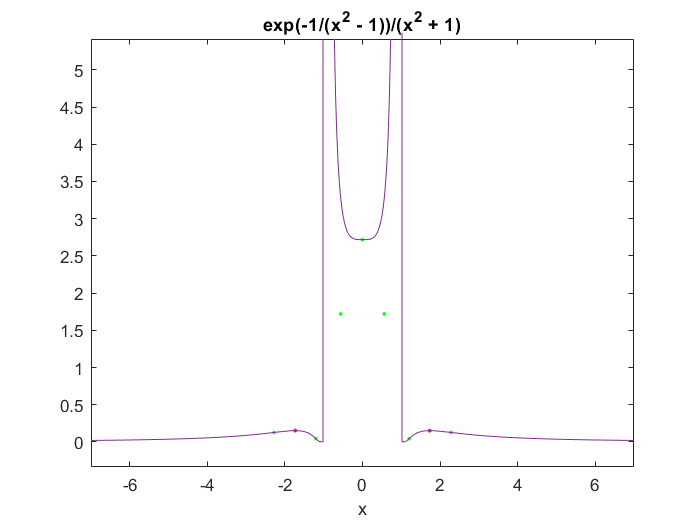

ezplot(f_x, [-7 7]);
hold off;